First lets load the audio signal source to be transmitted in each channel.

fileName=['/home/rodrigo/audio/channel_1.wav']; %name of first file
[x1,Fs]=readwav(fileName); %Fs is the sampling frequency (Hz)
fileName=['/home/rodrigo/audio/channel_2.wav']; %name of first file
[x2,Fs]=readwav(fileName); %Fs is the sampling frequency (Hz)
Nsamples = length(x1);


Now lets create a carrier for each desired carrier frequency and multiply by each upsampled message signal.

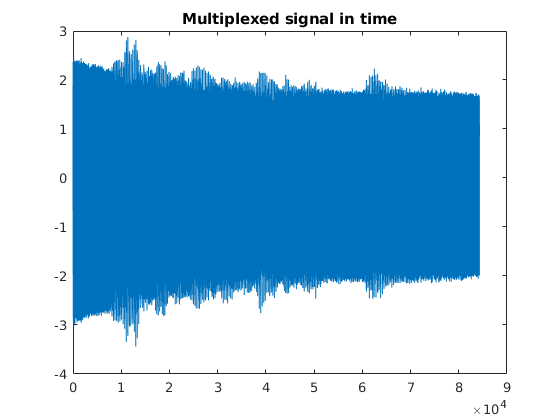

Fs_tx = 44e3;
modulation_index = 1;
%-6.34 -> -5
%28.7 -> 30
[s_t, v] = modulate_multiplex(x1,x2,Fs_tx,Fs,modulation_index,28.7);
plot(s_t);
title(['Multiplexed signal in time']);

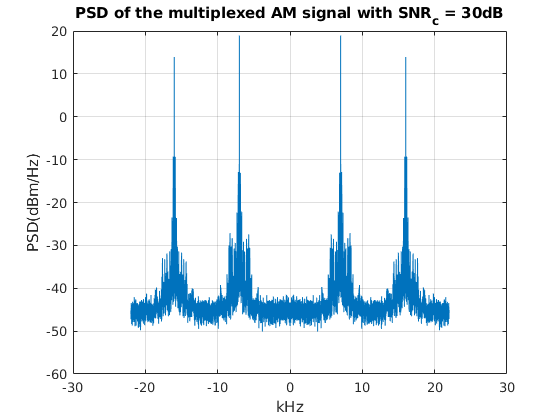

[psdIndB,f]=ak_psd(s_t,Fs_tx);
plot(f/1e3,psdIndB);
title(['PSD of the multiplexed AM signal with SNR_c = 30dB']);
xlabel('kHz') ;
ylabel('PSD(dBm/Hz)');
grid on

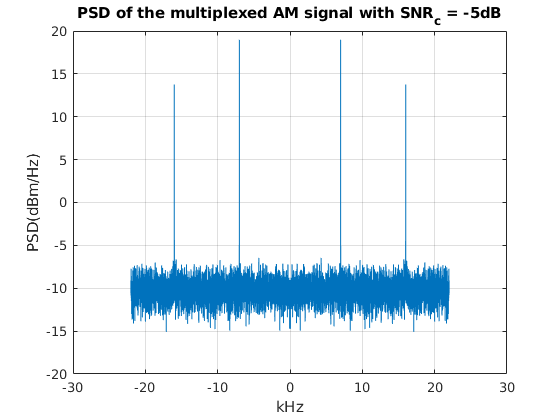

[s_t, v] = modulate_multiplex(x1,x2,Fs_tx,Fs,modulation_index,-6.34);
[psdIndB,f]=ak_psd(s_t,Fs_tx);
plot(f/1e3,psdIndB);
title(['PSD of the multiplexed AM signal with SNR_c = -5dB']);
xlabel('kHz') ;
ylabel('PSD(dBm/Hz)');
grid on

Now lets demodulate this AM signal and extract the message signal transmitted in each channel.

## Design three filters, which will operate at Fs, Fs/2 and Fsfinal

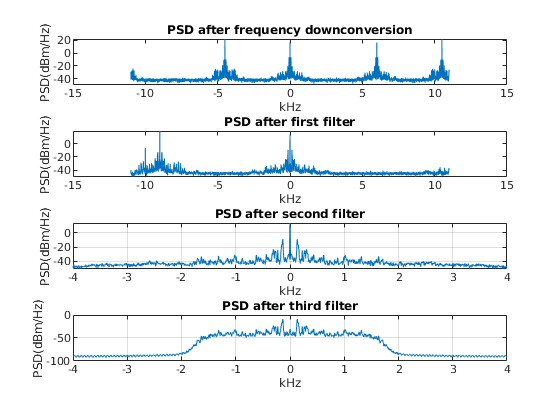

Fcutoff1 = 17e3; %cutoff is less than BW of all radio stations
Fcutoff2 = 10e3; %cutoff was chosen as 10 kHz
Fcutoff3 = 1.5e3; %filter cutoff frequency
Fsfinal = Fs; % Final sampling frequency

[s_t, v] = modulate_multiplex(x1,x2,Fs_tx,Fs,modulation_index,28.7);
xhat = demultiplex_demodulate(s_t,Fs_tx,Fsfinal,Fcutoff1, Fcutoff2, Fcutoff3, 16e3,1);

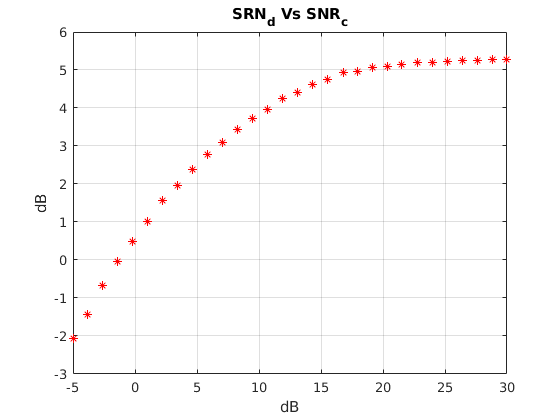

soundsc(transpose(xhat),Fs);
Pv_factor_vector = linspace(-6.34,28.7,30);
SNR_C_x1 = zeros(1,length(Pv_factor_vector_x1));
SNR_D_x1 = zeros(1,length(Pv_factor_vector_x1));
for i = 1:length(Pv_factor_vector)
    [s_t, v] = modulate_multiplex(x1,x2,Fs_tx,Fs,modulation_index,Pv_factor_vector(i));
    x1hat = demultiplex_demodulate(s_t,Fs_tx,Fsfinal,Fcutoff1, Fcutoff2, Fcutoff3, 7e3,0);
    x1hat = x1hat(1:length(x1));
    x2hat = demultiplex_demodulate(s_t,Fs_tx,Fsfinal,Fcutoff1, Fcutoff2, Fcutoff3, 16e3,0);
    x2hat = x2hat(1:length(x2));
    SNR_C_x1(i) = SNR_c(s_t-v,v);
    SNR_D_x1(i) = SNR_d(transpose(x1),transpose(x2),x1hat,x2hat);
end

subplot(1,1,1)
plot(SNR_C_x1,10*log10(SNR_D_x1),'r*')
title(['SRN_d Vs SNR_c']);
xlabel('dB') ;
ylabel('dB');
grid on

%Functions

function [s,v] = modulate_multiplex(x1,x2,Fs_tx,Fs,modulation_index,Pv_factor)
    m_t1 = transpose(x1);
    m_t2 = transpose(x2);
    U = Fs_tx/Fs;
    M = length(m_t1);
    n = [1:M*U+1]*1/Fs_tx;
    m_t_up1 = resample(m_t1, Fs_tx, Fs);
    m_t_up2 = resample(m_t2, Fs_tx, Fs);
    A1 = max(abs(m_t_up1))/modulation_index;
    A2 = max(abs(m_t_up2))/modulation_index;
    F_rx = [7, 16]*1000;
    s = n*0;
    phase = 2*pi/2;
    for i=1:2
        c_t_i = 1*cos(2*pi*F_rx(i)*n+phase);
        if i == 1
            s_t_i = times((A1+m_t_up1),c_t_i);
        else
            s_t_i = times((A2+m_t_up2),c_t_i);
        end
        s = s + s_t_i;
    end
    news = awgn(s,Pv_factor);
    v = news -s;
    s = news;
end

function r_t = demultiplex_demodulate(s_t,Fs_tx,Fsfinal,Fcutoff1, Fcutoff2, Fcutoff3, Fcarrier, show)
    %1) Filter to operate at Fs and eliminate the negative freq. image
    Norder1=10; %first filter order
    [B1,A1]=butter(Norder1,Fcutoff1/(Fs_tx/2)); %design IIR at Fs
    %2) Filter to operate at Fs/2
    Norder2=10; %first filter order
    [B2,A2]=butter(Norder2,Fcutoff2/((Fs_tx/2)/2)); %design IIR at Fs/2
    %3) Filter to operate at Fsfinal
    Norder3=12; %third filter order
    [B3,A3]=butter(Norder3,Fcutoff3/(Fsfinal/2)); %IIR filter at Fsfinal
    n = [1:length(s_t)]/Fs_tx;
    recover_carrier = exp(-j*2*pi*Fcarrier*n); %carrier
    %recover_carrier = cos(2*pi*F_carrier_i*n+phase);
    r_t = times(s_t,recover_carrier); % Perform the frequency downconversion
    if show ==1
        subplot(411); 
        [psdIndB,f]=ak_psd(r_t,Fs_tx/2);
        plot(f/1e3,psdIndB);
        title(['PSD after frequency downconversion']);
        xlabel('kHz') 
        ylabel('PSD(dBm/Hz)')
    end
    
    dataIn = r_t;
    dataOut = filter(B1,A1,dataIn); % First filter to eliminate the mirror image
    r_t = dataOut;
    r_t = resample(r_t,1,2); % Reduce the sampling frequency in half
    if show ==1
        subplot(412); 
        [psdIndB,f]=ak_psd(r_t,Fs_tx/2);
        plot(f/1e3,psdIndB);
        title(['PSD after first filter']);
        xlabel('kHz') 
        ylabel('PSD(dBm/Hz)')
    end
    
    dataIn = r_t;
    dataOut = filter(B2,A2,dataIn);
    r_t = dataOut;
    r_t = resample(r_t, Fsfinal, Fs_tx/2);
    if show == 1
        subplot(413);
        [psdIndB,f]=ak_psd(r_t,Fsfinal);
        plot(f/1e3,psdIndB);
        title(['PSD after second filter']);
        xlabel('kHz'); 
        ylabel('PSD(dBm/Hz)'); 
        grid on;
    end
    
    r_t = abs(r_t);
    r_t = r_t - mean(r_t);
    dataIn = r_t;
    dataOut = filter(B3,A3,dataIn);
    r_t = dataOut;
    if show ==1
        subplot(414);
        [psdIndB,f]=ak_psd(r_t,Fsfinal);
        plot(f/1e3,psdIndB);
        maxSpectrum = max(psdIndB)-5;
        title(['PSD after third filter']);
        xlabel('kHz') ;
        ylabel('PSD(dBm/Hz)');
        grid on;
    end
end

function sn = SNR_i(x,xhat)
    x = abs(x);
    x = x.^2;
    diff = abs(x-xhat);
    diff = diff.^2;
    sn = mean(x)/mean(diff);
end

function sn = SNR_d(x1,x2,x1hat,x2hat)
    snr1 = SNR_i(x1,x1hat);
    snr2 = SNR_i(x2,x2hat);
    sn = (snr1+snr2)/2;
end

function sn = SNR_c(x,v)
    P_x = 1*(sum(x.^2)) /length(x);
    P_v = 1*(sum(v.^2)) /length(v);
    sn = 10*log10(P_x/P_v);
end